clear;
rng('default');
% EEGdata = readtable('data/EEG-data.csv');
EEGdata = readtable('EEG-data.csv');

## Plot signal

rowIndex = 102;
row_data = EEGdata{rowIndex, 2:end-1};
figure;
plot(row_data);

% Add labels and title
xlabel('Time');
ylabel('milliVolts');
title(sprintf('EEG signal: %d', EEGdata{rowIndex, end})); % variable interpolation
clear row_data; clear rowIndex;

## Divide train and test data

rng('default');

% Extract data for each class
data_class3 = EEGdata(EEGdata.y == 3, :);
data_class4 = EEGdata(EEGdata.y == 4, :);

% Number of patients in each class
size_class3 = size(data_class3, 1);
size_class4 = size(data_class4, 1);

% Randomly select 20% of data from each class as the test set
test_idx_class3 = randperm(size_class3, ceil(0.2 * size_class3));
test_data_class3 = data_class3(test_idx_class3, :);
train_data_class3 = data_class3(setdiff(1:size_class3, test_idx_class3), :);

test_idx_class4 = randperm(size_class4, ceil(0.2 * size_class4));
test_data_class4 = data_class4(test_idx_class4, :);
train_data_class4 = data_class4(setdiff(1:size_class4, test_idx_class4), :);

% Combine test data and train data
test_data = [test_data_class3; test_data_class4];
train_data = [train_data_class3; train_data_class4];

train_data = train_data(randperm(size(train_data, 1)), :);

clear data_class3, clear data_class4, clear size_class3, clear size_class4, clear test_idx_class3, 
clear test_idx_class4, clear test_data_class3, clear test_data_class4, clear train_data_class3, clear train_data_class4;

## Compute means, std, median and IQR

% Initialize means_table with the correct size and fill it with NaNs
mean_table = nan(5, width(train_data) - 1);
std_table = nan(5, width(train_data) - 1);
median_table = nan(5, width(train_data) - 1);
Q1 = nan(5, width(train_data) - 1);
Q3 = nan(5, width(train_data) - 1);

% Iterate over each epilepsy level
for level = 1:5
    % Extract rows corresponding to the current epilepsy level
    rows_for_level = train_data(train_data.y == level, 2:end);

    % Calculate the mean of each column for the current epilepsy level
    mean_table(level, :) = mean(rows_for_level{:,:}, 'omitnan');
    std_table(level, :) = std(rows_for_level{:,:}, 'omitnan');
    median_table(level, :) = median(rows_for_level{:,:}, 'omitnan');
    Q1(level, :) = quantile(rows_for_level{:,:}, 0.25);
    Q3(level, :) = quantile(rows_for_level{:,:}, 0.75);
end

clear rows_for_level;

% Create a table with mean values and standard deviation
mean_table = array2table(mean_table, 'VariableNames', train_data.Properties.VariableNames(2:end));
std_table = array2table(std_table, 'VariableNames', train_data.Properties.VariableNames(2:end));
median_table = array2table(median_table, 'VariableNames', train_data.Properties.VariableNames(2:end));
Q1 = array2table(Q1, 'VariableNames', train_data.Properties.VariableNames(2:end));
Q3 = array2table(Q3, 'VariableNames', train_data.Properties.VariableNames(2:end));
IQR = Q3 - Q1;

% Create a vector representing the mean plus 2 standard deviations for each column
mean_plus_2_std_vector = mean_table + (2 .* std_table);
mean_minus_2_std_vector = mean_table - (2 .* std_table);

% % Plot mean of each level and mean plus/minus standard deviation
% for level = 1:5
%     figure;
%     hold on;
%     plot(mean_plus_2_std_vector{level, 2:end-1}, 'DisplayName', 'Mean + 2 Std');
%     plot(mean_table{level, 2:end-1}, 'DisplayName', 'Mean');
%     plot(mean_minus_2_std_vector{level, 2:end-1}, 'DisplayName', 'Mean - 2 Std');
%     hold off;
%     xlabel('Time');
%     ylabel('milliVolts');
%     title(sprintf("EEG signal for epilepsy level: %d", level));
%     legend('show');
% end

## Plot means

% Means plot
figure;
hold on;
% for i = 1:height(mean_table)
for i = 3:4
    plot(mean_table{i, 1:end-1}, 'DisplayName', sprintf('Class %d', mean_table{i, "y"}));
    xlabel('Time');
    ylabel('milliVolts');
    title("EEG signal");
    legend('show');
end

## Robust scale it

robust_EEGdata = nan(size(train_data));
zscore_EEGdata = nan(size(train_data));

for pz = 1:size(train_data, 1)
    pz_level = train_data{pz, end}; % Extract epilepsy level
    robust_EEGdata(pz, 1) = train_data{pz, "Var1"}; % Assign patient ID
    robust_EEGdata(pz, end) = pz_level; % Assign epilepsy level
    robust_EEGdata(pz, 2:end-1) = (train_data{pz, 2:end-1} - median_table{pz_level, 1:end-1}) ./ IQR{pz_level, 1:end-1};

    % zscore_EEGdata(pz, 1) = train_data{pz, "Var1"}; % Assign patient ID;
    % zscore_EEGdata(pz,end) = pz_level;
    % zscore_EEGdata(pz, 2:end-1) = (train_data{pz, 2:end-1} - mean_table{pz_level, 1:end-1}) ./ std_table{pz_level, 1:end-1};
end
clear pz_level, clear pz;

% Copy column names from EEGdata to robust_scaled
robust_EEGdata = array2table(robust_EEGdata, 'VariableNames', train_data.Properties.VariableNames);
% zscore_EEGdata = array2table(zscore_EEGdata, 'VariableNames', train_data.Properties.VariableNames);

% Initialize tables to store mean and standard deviation values
robust_mean = nan(5, width(robust_EEGdata) - 1);
robust_std = nan(5, width(robust_EEGdata) - 1);
robust_Q1 = nan(5, width(robust_EEGdata) - 1);
robust_Q3 = nan(5, width(robust_EEGdata) - 1);

% Iterate over each normalized epilepsy level
for level = 1:5

    if level == 1 || level == 2 || level == 5
        continue
    end

    % Extract rows corresponding to the current epilepsy level
    robust_rows_for_level = robust_EEGdata(robust_EEGdata.y == level, 2:end);
    
    % Calculate the mean of each column for the current epilepsy level
    robust_mean(level, :) = mean(robust_rows_for_level{:,:}, 'omitnan');
    robust_std(level, :) = std(robust_rows_for_level{:,:}, 'omitnan');
    robust_Q1(level, :) = quantile(robust_rows_for_level{:,:}, 0.25);
    robust_Q3(level, :) = quantile(robust_rows_for_level{:,:}, 0.75);
end
clear robust_rows_for_level; clear level;

robust_IQR = robust_Q3-robust_Q1;

% Create a table with mean values and standard deviation
robust_mean = array2table(robust_mean, 'VariableNames', train_data.Properties.VariableNames(2:end));
robust_std = array2table(robust_std, 'VariableNames', train_data.Properties.VariableNames(2:end));
robust_Q1 = array2table(robust_Q1, 'VariableNames', train_data.Properties.VariableNames(2:end));
robust_Q3 = array2table(robust_Q3, 'VariableNames', train_data.Properties.VariableNames(2:end));
robust_IQR = array2table(robust_IQR, 'VariableNames', train_data.Properties.VariableNames(2:end));

## Identify outliers

% Define lower and upper bounds for outliers for each feature
% Range for non-normalized data
lower_bound = robust_Q1 - 1.5 .* robust_IQR;
upper_bound = robust_Q3 + 1.5 .* robust_IQR;

% Range for robust data
robust_mean_plus_2_std = robust_mean + (2 .* robust_std);
robust_mean_minus_2_std = robust_mean - (2 .* robust_std);

num_features_above_threshold = zeros(size(EEGdata, 1), 1);
num_robust_features_above_threshold = zeros(size(EEGdata, 1), 1);

% Compute the number of features outside lower-upper bound
for i=1:size(train_data, 1)
    
    robust_patient = robust_EEGdata{i,2:end};
    pz_level = robust_EEGdata{i, end};

    % Compute the number of features above the threshold for the current row
    % num_features_above_threshold(i) = sum(robust_patient < lower_bound{pz_level,:} | robust_patient > upper_bound{pz_level,:});
    num_robust_features_above_threshold(i) = sum(robust_patient < robust_mean_minus_2_std{pz_level,:} | robust_patient > robust_mean_plus_2_std{pz_level,:});

end
clear i; clear pz_level; clear patient; clear robust_patient;


## Count outliers

thresholds = 0.05:0.01:0.2;

% Convert thresholds to strings
threshold_str = arrayfun(@(x) [num2str(x*100), ' %'], thresholds, 'UniformOutput', false);
nr_outliers_by_threshold = zeros(1, numel(thresholds));

for i = 1:numel(thresholds)
    outlier_threshold = thresholds(i) * size(robust_EEGdata, 2);
    nr_outliers_by_threshold(i) = sum(num_robust_features_above_threshold > outlier_threshold);
end
nr_outliers_by_threshold = array2table(nr_outliers_by_threshold, 'VariableNames', threshold_str);

outlier_threshold = 0.2 * size(robust_EEGdata, 2); % 10% of features
outliers_logic_array = num_robust_features_above_threshold > outlier_threshold;
robust_outliers_ids = robust_EEGdata.Var1(outliers_logic_array)

robust_outliers_ids =    499
   461
   367
   174


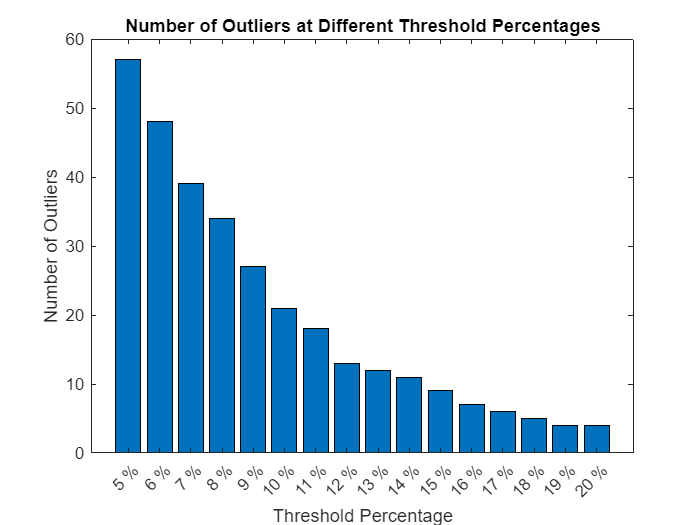


% Plot the robust_outliers_table
figure;
bar(1:numel(threshold_str), nr_outliers_by_threshold{:,:}, 'stacked');
xticks(1:numel(threshold_str));
xticklabels(threshold_str);
xlabel('Threshold Percentage');
ylabel('Number of Outliers');
title('Number of Outliers at Different Threshold Percentages');

## Plot Robust mean and + - 2 StdDev

% % Plot mean of each level and mean plus/minus standard deviation
% for level = 1:5
%     figure;
%     hold on;
%     plot(robust_mean_plus_2_std_vector{level, 2:end-1}, 'DisplayName', 'Robust Mean + 2 Std');
%     plot(robust_mean_table{level, 2:end-1}, 'DisplayName', 'Robust Mean');
%     plot(robust_mean_minus_2_std_vector{level, 2:end-1}, 'DisplayName', 'Robust Mean - 2 Std');
%     hold off;
%     xlabel('Time');
%     ylabel('milliVolts');
%     title(sprintf("Robust EEG signal for epilepsy level: %d", level));
%     legend('show');
% end

## Training

% Remove outliers from training data
outlier_logical_index = ismember(train_data.Var1, robust_outliers_ids);
train_data = train_data(~outlier_logical_index, :);
size(train_data)

ans =          156        4096


## Optimize hyperparameters

rng('default');

% Define hyperparameters and search space
kernels = {'linear', 'rbf', 'polynomial'};
box_constraints = [0.8, 0.9, 1, 2];
kernel_scales = [1, 5];
max_combinations = numel(kernels)*numel(box_constraints)*numel(kernel_scales);
% Choose a validation scheme
K = 5;
indices_class3 = crossvalind('Kfold', sum(train_data.y == 3), K);
indices_class4 = crossvalind('Kfold', sum(train_data.y == 4), K);
indices = [indices_class3; indices_class4];
indices = indices(randperm(size(indices,1)),:);


% Perform hyperparameter search
best_score = 0;
avg_metrics = array2table(nan(max_combinations, 11), 'VariableNames', ["Avg Accuracy", "Std Accuracy", "Avg Sensitivity", ...
    "Std Sensitivity", "Avg Specificity", "Std Specificity", "Avg FPR", "Std FPR",...
   "Kernel", "BoxConstraint", "KernelScale"]);
avg_metrics.Kernel = num2cell(avg_metrics.Kernel); % Convert the column to cell to save strings
iteration = 0;

% Change it to false to skip Grid Search if it has already been performed
% (a.k.a. avg_metrics is available)
already_trained = false;
% already_trained = true;

% Loop through kernels
for k=1:numel(kernels)

    % Skip the Grid Search if it has already been computed
    if already_trained
        load ('data/avg_metrics.mat')
        break
    end

    kernel = kernels{k};
    % Loop through box constraints
    for bc=1:numel(box_constraints)
        box_constraint = box_constraints(bc);
        % Loopkernel through kernel scales
        for ks=1:numel(kernel_scales)
            kernel_scale = kernel_scales(ks);

            iteration = iteration + 1;

            % To store metrics of hyperparameters
            hyperparam_metrics = array2table(nan(K, 4), 'VariableNames', ["Accuracy", "Sensitivity", "Specificity","FPR"]);

            fprintf('iteration %d kernel %s box_constraint %.1f kernel_scale %.1f \n', iteration, kernel, box_constraint, kernel_scale)

            for cluster_idx = 1:K
                % Metrics
                accuracy = 0;
                sensitivity = 0;
                specificity = 0;
                true_positives = 0;
                true_negatives = 0;

                % Extract training and testing data based on current fold
                temp_train_set = indices ~= cluster_idx; 
                temp_validation_set = ~temp_train_set;
            
                temp_train_data = train_data(temp_train_set, 2:end-1);
                temp_validation_data = train_data(temp_validation_set, 2:end-1); 
            
                temp_train_labels = train_data.y(temp_train_set);
                temp_validation_labels = train_data.y(temp_validation_set);
                
                % Train SVM with current hyperparameters
                svmStruct = fitcsvm(temp_train_data, temp_train_labels, ...
                    'KernelFunction', kernel, ...
                    'BoxConstraint', box_constraint, ...
                    'KernelScale', kernel_scale, ...
                    'Standardize', false);
                svmStruct = compact(svmStruct);
                
                % Test SVM model
                predictions = predict(svmStruct, temp_validation_data);        
        
                % Update metrics
                true_positives = sum(predictions == 4 & temp_validation_labels == 4); % Count of true positive predictions (class 4)
                true_negatives = sum(predictions == 3 & temp_validation_labels == 3); % Count of true negative predictions (class 3)
        
                sensitivity = sensitivity + true_positives / sum(temp_validation_labels == 4);
                specificity = specificity + true_negatives / sum(temp_validation_labels == 3);
                fpr = 1 - specificity;
                accuracy = accuracy + mean(predictions == temp_validation_labels);
        
                % Save metrix of sampling cluster_idx into the metrics table
                % score = accuracy*sensitivity*specificity;
                hyperparam_metrics{cluster_idx, 1:4} = [accuracy, sensitivity, specificity,fpr];
            end

            hyperparam_metrics;
            avg_accuracy = mean(hyperparam_metrics.Accuracy);
            avg_sensitivity = mean(hyperparam_metrics.Sensitivity);
            avg_specificity = mean(hyperparam_metrics.Specificity);
            avg_fpr = mean(hyperparam_metrics.FPR);
            std_accuracy = std(hyperparam_metrics.Accuracy);
            std_sensitivity = std(hyperparam_metrics.Sensitivity);
            std_specificity = std(hyperparam_metrics.Specificity);
            std_fpr = std(hyperparam_metrics.FPR);

            avg_metrics{iteration, 1:8} = [avg_accuracy, std_accuracy, avg_sensitivity, std_sensitivity, ...
                avg_specificity, std_specificity,avg_fpr,std_fpr];
            avg_metrics{iteration, 9} = {kernel};
            avg_metrics{iteration, 10:11} = [box_constraint, kernel_scale];
            avg_metrics;
        end
    end
end

iteration 1 kernel linear box_constraint 0.8 kernel_scale 1.0 
iteration 2 kernel linear box_constraint 0.8 kernel_scale 5.0 
iteration 3 kernel linear box_constraint 0.9 kernel_scale 1.0 
iteration 4 kernel linear box_constraint 0.9 kernel_scale 5.0 
iteration 5 kernel linear box_constraint 1.0 kernel_scale 1.0 
iteration 6 kernel linear box_constraint 1.0 kernel_scale 5.0 
iteration 7 kernel linear box_constraint 2.0 kernel_scale 1.0 
iteration 8 kernel linear box_constraint 2.0 kernel_scale 5.0 
iteration 9 kernel rbf box_constraint 0.8 kernel_scale 1.0 
iteration 10 kernel rbf box_constraint 0.8 kernel_scale 5.0 
iteration 11 kernel rbf box_constraint 0.9 kernel_scale 1.0 
iteration 12 kernel rbf box_constraint 0.9 kernel_scale 5.0 
iteration 13 kernel rbf box_constraint 1.0 kernel_scale 1.0 
iteration 14 kernel rbf box_constraint 1.0 kernel_scale 5.0 
iteration 15 kernel rbf box_constraint 2.0 kernel_scale 1.0 
iteration 16 kernel rbf box_constraint 2.0 kernel_scale 5.0 
iteration

## Sort and find best

avg_metrics

avg_metrics = 24×11 table
    Avg Accuracy    Std Accuracy    Avg Sensitivity    Std Sensitivity    Avg Specificity    Std Specificity    Avg FPR    Std FPR       Kernel      BoxConstraint    KernelScale
    ____________    ____________    _______________    _______________    _______________    _______________    _______    ________    __________    _____________    ___________

      0.69899         0.023893          0.57291           0.064461            0.84182           0.096548        0.15818    0.096548    {'linear'}         0.8              1     
      0.70504         0.015933          0.58541           0.05155

sorted_avg_metrics = sortrows(avg_metrics, 'Avg Sensitivity', 'descend')

sorted_avg_metrics = 24×11 table
    Avg Accuracy    Std Accuracy    Avg Sensitivity    Std Sensitivity    Avg Specificity    Std Specificity    Avg FPR    Std FPR         Kernel        BoxConstraint    KernelScale
    ____________    ____________    _______________    _______________    _______________    _______________    _______    ________    ______________    _____________    ___________

      0.48105         0.083853          0.92147           0.050051           0.023026           0.031723        0.97697    0.031723    {'polynomial'}         0.8              5     
      0.48105         0.083853          0.9214

% I choose box = 1, scale = 5 for linear (which has uniform results over the hyperparameters), box = 1, scale = 1 for rbf
% (in this case nothing changes with the change of the values), box = 1,
% scale = 5 for polynomial (in this case the scale plays an important role)

## Check metrics of Model with selected Hyperparameters

rng('default');
[final_metricsL, avg_final_svmL, std_final_svmL, final_svmsL] = train_svm_with_crossval(train_data, 5, 'linear', 1, 5)

final_metrics = 5×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)      FPR  
    ________    _________________    ___________________    _______

    0.71875           0.5625                 0.875            0.125
    0.67742          0.58824               0.78571          0.21429
    0.70968          0.52632                     1                0
    0.70968          0.58333               0.78947          0.21053
    0.70968          0.66667                  0.75             0.25


avg_final_svm = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)      FPR  
    ________    _________________    ___________________    _______

    0.70504          0.58541               0.84004          0.15996


std_final_svm = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)      FPR   
    ________    _________________    ___________________    ________

    0.01425         0.046113              0.089916          0.089916


final_svms = 5×1 cell array
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}


[final_metricsR, avg_final_svmR, std_final_svmR, final_svmsR] = train_svm_with_crossval(train_data, 5, 'rbf', 1, 1)

final_metrics = 5×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)    FPR
    ________    _________________    ___________________    ___

        0.5             1                     0              1 
    0.45161             0                     1              0 
     0.3871             0                     1              0 
     0.3871             1                     0              1 
    0.48387             1                     0              1 


avg_final_svm = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)    FPR
    ________    _________________    ___________________    ___

    0.44194            0.6                   0.4            0.6


std_final_svm = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)     FPR  
    ________    _________________    ___________________    ______

    0.047409         0.4899                0.4899           0.4899


final_svms = 5×1 cell array
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}


[final_metricsP, avg_final_svmP, std_final_svmP, final_svmsP] = train_svm_with_crossval(train_data, 5, 'polynomial', 1, 5)

final_metrics = 5×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)      FPR  
    ________    _________________    ___________________    _______

     0.4375            0.875                     0                1
    0.48387          0.88235                     0                1
     0.6129                1                     0                1
     0.3871          0.91667              0.052632          0.94737
    0.48387          0.93333                0.0625           0.9375


avg_final_svm = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)      FPR  
    ________    _________________    ___________________    _______

    0.48105          0.92147              0.023026          0.97697


std_final_svm = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)      FPR   
    ________    _________________    ___________________    ________

     0.075          0.044767              0.028373          0.028373


final_svms = 5×1 cell array
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}
    {1×1 classreg.learning.classif.CompactClassificationSVM}


## Train final models

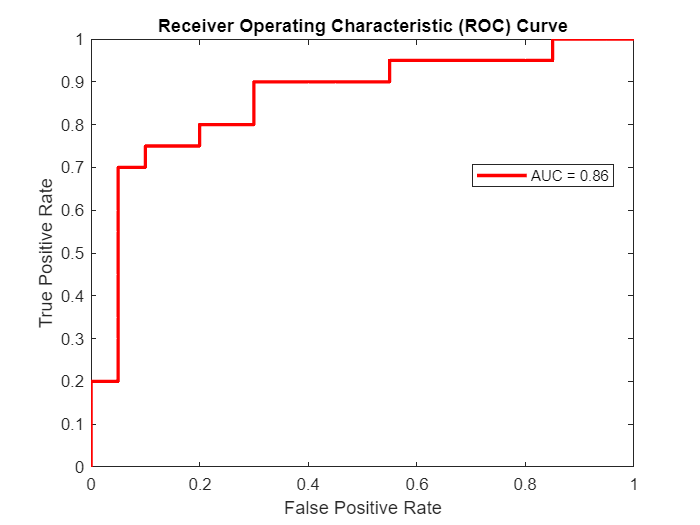

lin_svm_metrics = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)    FPR 
    ________    _________________    ___________________    ____

      0.75            0.55                  0.95            0.05


rng('default');

% Test final model against test data
% Final linear SVM
final_svmL = fitcsvm(train_data(:, 2:end-1), train_data.y, 'KernelFunction', 'linear', ...
'Standardize', false, 'BoxConstraint', 1, 'KernelScale', 5);
lin_svm_metrics = evaluate_model(final_svmL, test_data)

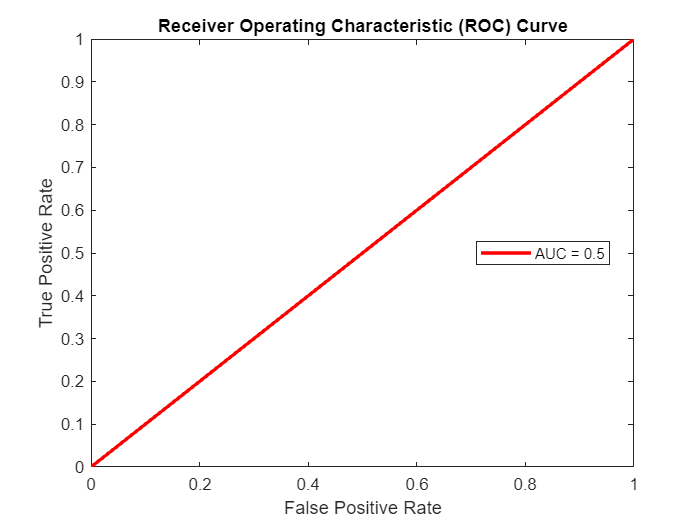

rbf_svm_metrics = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)    FPR
    ________    _________________    ___________________    ___

      0.5               1                     0              1 


rng('default');

% Final gaussian SVM
final_svmR = fitcsvm(train_data(:, 2:end-1), train_data.y, 'KernelFunction', 'rbf', ...
        'Standardize', false, 'BoxConstraint', 1, 'KernelScale', 1);

rbf_svm_metrics = evaluate_model(final_svmR, test_data)

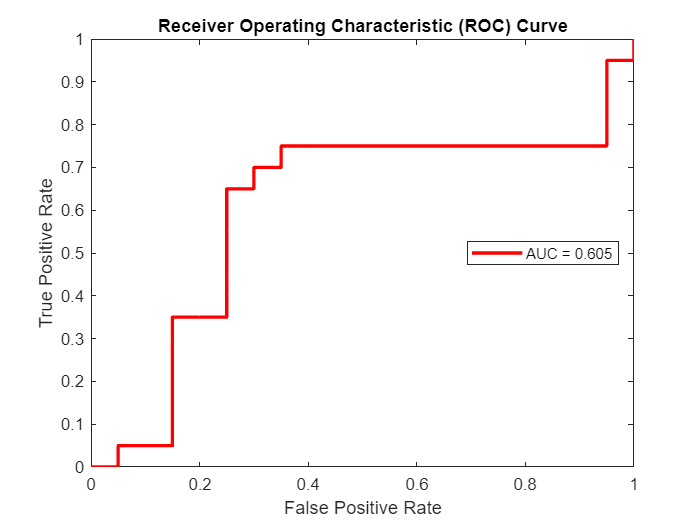

poly_svm_metrics = 1×4 table
    Accuracy    Sensitivity (TPR)    Specificity (1-FPR)    FPR 
    ________    _________________    ___________________    ____

      0.5             0.95                  0.05            0.95


rng('default');

% Final polynomial SVM
final_svmP = fitcsvm(train_data(:, 2:end-1), train_data.y, 'KernelFunction', 'polynomial', ...
        'Standardize', false, 'BoxConstraint', 1, 'KernelScale', 5);

poly_svm_metrics = evaluate_model(final_svmP, test_data)

## 2 Layers classifiers

rng('default');

nr_lvl_1_models = 3;
models_names = {'LIN_SVM', 'Decision_Tree', 'RF Bag'};

models = {}; % Save the models

train_data_size = size(train_data, 1);

% Create a random permutation of indices
indices = randperm(train_data_size);

% Determine the number of samples in the first part
split_idx = round(0.5 * train_data_size);

% Extract indices for the first part and second part
indices_fold1 = indices(1:split_idx);
indices_fold2 = indices(split_idx+1:end);

% Divide train_data in 2 sets
train_data_fold1 = train_data(indices_fold1, :);
train_data_fold2 = train_data(indices_fold2, :);

% Final linear SVM
lin_svm = fitcsvm(train_data(:, 2:end-1), train_data.y, 'KernelFunction', 'linear', ...
        'Standardize', false, 'BoxConstraint', 1, 'KernelScale', 5);
models{1} = lin_svm;

% Decision tree
tree_model = fitctree(train_data(:, 2:end-1), train_data.y, 'SplitCriterion', 'gdi', 'MaxNumSplits', 100);
models{2} = tree_model;

% Random Forest 
random_forest_bag = TreeBagger(100,train_data(:, 2:end-1), train_data.y, 'Method', 'classification');
models{3} = random_forest_bag;


## Save predictions of layer 1 classifiers

rng('default')
models_predictions = array2table(nan(size(train_data, 1), nr_lvl_1_models), 'VariableNames', models_names);
models_scores = array2table(nan(size(train_data, 1), nr_lvl_1_models), 'VariableNames', models_names);

for i = 1:nr_lvl_1_models
    if i == 3
        [preds, scores] = predict(models{i}, train_data);
        preds = str2double(preds);
    else  
    [preds, scores] = predict(models{i}, train_data);
    end
    models_predictions{:, i} = preds;
    models_scores{:, i} = scores(:, 1);
end

## Train level 2 classifiers and predict

rng('default');

models_names = {'LIN_SVM', 'Decision_Tree', 'RF Bag', ...
    'Stacked_Classifier_Scores'};

% Train on Scores of models
models{4} = TreeBagger(100,models_scores, train_data.y, 'Method', 'classification');

N = numel(models);

models_accuracy = array2table(nan(1, N), 'VariableNames', models_names);
models_specificity = array2table(nan(1, N), 'VariableNames', models_names);
models_sensitivity = array2table(nan(1, N), 'VariableNames', models_names);
models_fpr =  array2table(nan(1, N), 'VariableNames', models_names);

models_predictions_final = zeros(size(test_data, 1), N);
models_scores_final = zeros(size(test_data, 1), N);

for i = 1:N
    if i < 3
        disp(class(models{i}))
        evaluate_model(models{i}, test_data)
        [prediction, score] = predict(models{i}, test_data); % First 2 models (level 1)
    elseif  i == 3
        disp(class(models{i}))
        evaluate_modelRF(models{i}, test_data)   % function ad hoc for evaluating Randomforest (TreeBagger): simply the predictions and the scores have to be converted from string to double
        [prediction, score] = predict(models{i}, test_data); % Third model (level 1)
        prediction = str2double(prediction);
else
        [prediction, score] = predict(models{i}, models_scores_final(:, 1:3)); % Stacked Classifiers trained on Scores
        prediction = str2double(prediction);
    end
    

    accuracy = 0;
    sensitivity = 0;
    specificity = 0;

    models_predictions_final(:, i) = prediction;
    models_accuracy{:, i} = numel(find(models_predictions_final(:, i) == test_data.y)) / numel(test_data.y);

    % Update metrics
    true_positives = sum(models_predictions_final(:, i) == 4 & test_data.y == 4);
    true_negatives = sum(models_predictions_final(:, i) == 3 & test_data.y == 3);

    % Sensitivity (True Positive Rate)
    models_sensitivity{:, i} = sensitivity + true_positives / sum(test_data.y == 4);

    % Specificity (True Negative Rate)
    models_specificity{:, i} = specificity + true_negatives / sum(test_data.y == 3);
    models_fpr{:,i} = 1 -specificity;
end
models_accuracy
models_sensitivity
models_specificity

## Frequency analyser

% @see https://it.mathworks.com/help/matlab/ref/fft.html#
[frequencies, P1_train_data] = calculate_fft(train_data)
[frequencies, P1_test_data] = calculate_fft(test_data)
sum(P1_train_data.y == 3)
sum(P1_train_data.y == 4)
sum(P1_test_data.y == 3)
sum(P1_test_data.y == 4)

## Compute mean spectrum for class 3 and class 4

idx_class3 = P1_train_data.y == 3;
idx_class4 = P1_train_data.y == 4;
mean_class3 = mean(P1_train_data(idx_class3, 2:end-1), 1)
std_class3 = std(P1_train_data(idx_class3, 2:end-1), 1)
mean_class4 = mean(P1_train_data(idx_class4, 2:end-1), 1)
std_class4 = std(P1_train_data(idx_class4, 2:end-1), 1)
distance = (mean_class4-mean_class3).^2
figure, hold on
plot(frequencies, mean_class3{1, :})
plot(frequencies, mean_class4{1, :})

## Test SVM on frequencies

rng('default');

rf_freq = fitcensemble(P1_train_data(:, 2:end-1), P1_train_data.y, "Method", "Bag");
test_metrics = evaluate_model(rf_freq, P1_test_data)

svm_freq = fitcsvm(P1_train_data(:, 2:end-1), P1_train_data.y, "KernelFunction", "linear", "BoxConstraint", 1, "KernelScale", 1, 'Standardize', false);
[freq_metrics, avg_freq_metrics, std_freq_metrics, ~] = train_svm_with_crossval(P1_train_data, 5, 'linear', 1, 1)
test_metrics = evaluate_model(svm_freq, P1_test_data)

## Repeat test with random combinations of splits

[test_freq_metrics, final_metrics] = test_freq_model_random_seeds(EEGdata, 20, 0.2)

## Plot single-sided specttrum

% Plot the single-sided magnitude spectrum
for i = 1:0
    figure;
    P1_train_data_shuffled = P1_train_data(randperm(size(P1_train_data, 1)), :);
    plot(frequencies(2: ...
        end), P1_train_data_shuffled{i, 3:end-1}, "LineWidth", 1)
    title(sprintf('Single-Sided Amplitude Spectrum of the Signal class %d ', P1_train_data_shuffled{i, end}))
    xlabel('Frequency')
    ylabel('|Y(f)|')
end

## Group spectrum data into bins = 10 -> do not do it

grouped_P1 = nan(size(P1_train_data, 1), 3 + size(P1_train_data, 2) / 10); % +3 because Var1, y and DC frequency

function [metrics, avg_svm, std_svm, svm_models] = train_svm_with_crossval(train_data, K, kernel, box_constraint, kernel_scale)
% TRAIN_SVM_WITH_CROSSVAL: Trains SVM models with cross-validation.

    % Initialize output variables
    svm_models = cell(K, 1);
    metrics = array2table(nan(K, 4), 'VariableNames', ["Accuracy", "Sensitivity (TPR)", "Specificity (1-FPR)","FPR"]);
    
    rng('default');
    indices_class3 = crossvalind('Kfold', sum(train_data.y == 3), K);
    indices_class4 = crossvalind('Kfold', sum(train_data.y == 4), K);
    indices = [indices_class3; indices_class4];
    indices = indices(randperm(size(indices,1)),:);
    % indices = crossvalind('Kfold', size(train_data, 1), K);

    % Iterate over each fold
    for cluster_idx = 1:K

        % Metrics
        accuracy = 0;
        sensitivity = 0;
        specificity = 0;

        % disp(['K = ' num2str(cluster_idx)]);

        % Extract training and testing data based on current fold
        temp_train_set = indices ~= cluster_idx; 
        temp_validation_set = ~temp_train_set;

        temp_train_data = train_data(temp_train_set,:);
        temp_validation_data = train_data(temp_validation_set,:); 

        temp_train_labels = train_data.y(temp_train_set);
        temp_validation_labels = train_data.y(temp_validation_set);

        try
            % Train SVM model
            svmStruct = fitcsvm(temp_train_data, temp_train_labels, ...
                'KernelFunction', kernel, 'Standardize', false, 'BoxConstraint', box_constraint, 'KernelScale', kernel_scale);
            svmStruct = compact(svmStruct);

            % Test SVM model
            [predictions, ~] = predict(svmStruct, temp_validation_data);        
            
            % predictions = str2double(predictions);

            % Update metrics
            true_positives = sum(predictions == 4 & temp_validation_labels == 4); % Count of true positive predictions (class 4)
            true_negatives = sum(predictions == 3 & temp_validation_labels == 3); % Count of true negative predictions (class 3)

            % Sensitivity (True Positive Rate)
            sensitivity = sensitivity + true_positives / sum(temp_validation_labels == 4);

            % Specificity (True Negative Rate)
            specificity = specificity + true_negatives / sum(temp_validation_labels == 3);
            fpr = 1-specificity;
            % Overall accuracy
            accuracy = accuracy + mean(predictions == temp_validation_labels);

            % Save metrix of sampling cluster_idx into the metrics table
            score = accuracy * sensitivity * specificity;
            metrics{cluster_idx, 1:4} = [accuracy, sensitivity, specificity,fpr];
            % Save trained model
            svm_models{cluster_idx} = svmStruct;

        catch exception
            % Handle errors
            disp('Error occurred during model training/testing:');
            msgString = getReport(exception);
            disp(msgString);
        end
    end

    avg_svm = mean(metrics, 1);
    std_svm = std(metrics, 1);
end

function metrics = evaluate_model(model, test_data)

    metrics = array2table(nan(1, 4), 'VariableNames', ["Accuracy", "Sensitivity (TPR)", "Specificity (1-FPR)","FPR"]);

    % Initialize metrics
    accuracy = 0;
    sensitivity = 0;
    specificity = 0;

    % Extract features and labels from test data
    x_test = test_data(:, 2:end-1);
    y_test = test_data.y;

    % Test model
    [predictions, scores] = predict(model, x_test);        

    % Update metrics
    true_positives = sum(predictions == 4 & y_test == 4); % Count of true positive predictions (class 4)
    true_negatives = sum(predictions == 3 & y_test == 3); % Count of true negative predictions (class 3)

    % Overall accuracy
    accuracy = accuracy + mean(predictions == y_test);

    % Sensitivity (True Positive Rate)
    sensitivity = sensitivity + true_positives / sum(y_test == 4);

    % Specificity (True Negative Rate)
    specificity = specificity + true_negatives / sum(y_test == 3);
    fpr = 1-specificity;
    % Save metrics into the final_svm_metrics table
    score = accuracy * sensitivity * specificity;

    metrics{:, 1:4} = [accuracy, sensitivity, specificity,fpr];

    plot_curves(y_test, scores, 4);

end

function metrics = evaluate_modelRF(model, test_data)

    metrics = array2table(nan(1, 4), 'VariableNames', ["Accuracy", "Sensitivity (TPR)", "Specificity (1-FPR)","FPR"]);

    % Initialize metrics
    accuracy = 0;
    sensitivity = 0;
    specificity = 0;

    % Extract features and labels from test data
    x_test = test_data(:, 2:end-1);
    y_test = test_data.y;

    % Test RF model
    [predictions, scores] = predict(model, x_test);        

    predictions = str2double(predictions);

    % Update metrics
    true_positives = sum(predictions == 4 & y_test == 4); % Count of true positive predictions (class 4)
    true_negatives = sum(predictions == 3 & y_test == 3); % Count of true negative predictions (class 3)

    % Overall accuracy
    accuracy = accuracy + mean(predictions == y_test);

    % Sensitivity (True Positive Rate)
    sensitivity = sensitivity + true_positives / sum(y_test == 4);

    % Specificity (True Negative Rate)
    specificity = specificity + true_negatives / sum(y_test == 3);
    fpr = 1- specificity;
    % Save metrics into the final_svm_metrics table
    score = accuracy * sensitivity * specificity;

    metrics{:, 1:4} = [accuracy, sensitivity, specificity,fpr];

    plot_curves(y_test, scores, 4);

end

function plot_curves = plot_curves(y_test, scores, positive_label)
     % Compute ROC curve
    [fpr, tpr, ~, auc] = perfcurve(y_test, scores(:, 2), positive_label);
    
    % Plot ROC curve
    figure;
    plot(fpr, tpr, 'LineWidth', 2, 'Color', 'r');
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    title('Receiver Operating Characteristic (ROC) Curve');
    legend(['AUC = ' num2str(auc)], 'Location', 'Best');
    xlim([0 1]);
    ylim([0 1]);
    % grid on;
    
    % % Compute precision-recall curve
    % [precision, recall, ~, auc] = perfcurve(y_test, scores(:, 2), positive_label, 'xCrit', 'reca', 'yCrit', 'prec');
    % 
    % % Plot precision-recall curve
    % figure;
    % plot(recall, precision, 'LineWidth', 2, 'Color', 'r');
    % xlabel('Recall');
    % ylabel('Precision');
    % title('Precision-Recall Curve');
    % legend(['AUC = ' num2str(auc)], 'Location', 'Best');
    % xlim([0 1]);
    % ylim([0 1]);
    % % grid on;

end

function [frequencies, P1] = calculate_fft(data)
    nr_patients = size(data, 1);
    nr_columns = size(data, 2);
    
    L = nr_columns - 2; % Length of the signal: first and last column not considered
    
    fft_result = array2table(nan(nr_patients, nr_columns), 'VariableNames', data.Properties.VariableNames);
    P2 = array2table(nan(nr_patients, nr_columns), 'VariableNames', data.Properties.VariableNames);
    P1 = array2table(nan(nr_patients, L/2 + 3));
    
    % L = 4094. P1 is single-sided spectrum (2047) which is symmetric 
    % around the DC frequency ( = 0) so 2047 +1.
    % To this we add 2 columns for patient ID and epilepsy level -> L/2 + 3
    
    % Then we double the amplitudes except for DC and Nyquist frequencies
    % (first and last). In our case we have DC + 2047 readings (last is Nyquist
    % frequency. So we only double from the 2nd to the 2nd to last frequency.
    % Considering the first and last column are Var1 and y, then we double from
    % 2+1=3 to (end-1)-1=end-2 -> P1(3:end-2)
    
    Fs = 1; % Let's assume a unit sampling frequency (because it's not known)
    
    frequencies = Fs/L*(0:(L/2)); % Define frequency domain for single-sided spectrum (Fs of 1 unit since it's unknown)
    
    for pz = 1:nr_patients
        fft_result{pz, 1} = data{pz, 1};
        fft_result{pz, end} = data{pz, end};
        fft_result{pz, 2:end-1} = fft(data{pz, 2:end-1}); % Perform FFT
    
        % Compute the magnitude of the two-sided spectrum
        % Do not compute abs on Var1 and y. Divide fft_result by L
        P2{pz, 2:end-1} = abs(fft_result{pz, 2:end-1} / L);
        P2{pz, 1} = data{pz, 1}; % Assign pz ID
        P2{pz, end} = data{pz, end}; % Assign epilepsy level
        
        % Extract the single-sided spectrum
        % There is no need to multiply P1(1) and P1(end) by 2 since these amplitudes 
        % correspond to zero and Nyquist frequencies, respectively, 
        % and do not possess complex conjugate pairs in the negative frequencies.
        % L = 4094
        P1{pz, :} = P2{pz, 1:L/2 + 3}; % +2 instead of +1 so that i can substitute last column with epilepsy level
        P1{pz, end} = data{pz, end};
        P1{pz, 3:end-2} = 2*P1{pz, 3:end-2}; % Double the amplitudes (except DC and Nyquist frequencies)
    end
    
    % Rename columns from 2nd to one before the last
    for i = 2:size(P1,2)-1
        newName = ['X' num2str(i-1)]; % Generate new column name
        P1.Properties.VariableNames{i} = newName; % Rename the column
    end
    P1.Properties.VariableNames(1) = "Var1";
    P1.Properties.VariableNames(end) = "y";
end

function [test_freq_metrics, final_metrics] = test_freq_model_random_seeds(EEGdata, nr_seeds, split_amount)

    test_freq_metrics = array2table(nan(nr_seeds, 3), 'VariableNames', {'Accuracy', 'Sensitivity', 'Specificity'});

    for seed = 1:nr_seeds
        rng(seed); % Set random seed
        
        % Extract data for each class
        data_class3 = EEGdata(EEGdata.y == 3, :);
        data_class4 = EEGdata(EEGdata.y == 4, :);

        % Number of patients in each class
        size_class3 = size(data_class3, 1);
        size_class4 = size(data_class4, 1);

        % Randomly select % of data from each class as the test set
        test_idx_class3 = randperm(size_class3, ceil(split_amount * size_class3));
        test_idx_class4 = randperm(size_class4, ceil(split_amount * size_class4));

        % Split the data into test and train sets
        test_data_class3 = data_class3(test_idx_class3, :);
        test_data_class4 = data_class4(test_idx_class4, :);
        train_data_class3 = data_class3(setdiff(1:size_class3, test_idx_class3), :);
        train_data_class4 = data_class4(setdiff(1:size_class4, test_idx_class4), :);

        % Combine test data and train data
        test_data = [test_data_class3; test_data_class4];
        train_data = [train_data_class3; train_data_class4];

        % Convert to frequency domain
        [~, P1_train_data] = calculate_fft(train_data);
        [~, P1_test_data] = calculate_fft(test_data);
        
        svm_freq = fitcsvm(P1_train_data(:, 2:end-1), P1_train_data.y, ...
            "KernelFunction", "linear", "BoxConstraint", 2, "KernelScale", 5, 'Standardize', false);

        fprintf('Iteration %d ', seed)
        test_metrics = evaluate_model(svm_freq, P1_test_data);

        test_freq_metrics{seed, :} = [test_metrics.Accuracy, test_metrics.Sensitivity, test_metrics.Specificity];
    end

    final_metrics = array2table(nan(1, 6), 'VariableNames', {'Avg_Accuracy', 'Std_Accuracy', 'Avg_Sensitivity', ...
        'Std_Sensitivity', 'Avg_Specificity', 'Std_Specificity'});

    % Compute final metrics
    final_metrics(1, 1) = mean(test_freq_metrics(:, 1)); % Avg_Accuracy
    final_metrics(1, 2) = std(test_freq_metrics(:, 1));  % Std_Accuracy
    final_metrics(1, 3) = mean(test_freq_metrics(:, 2)); % Avg_Sensitivity
    final_metrics(1, 4) = std(test_freq_metrics(:, 2));  % Std_Sensitivity
    final_metrics(1, 5) = mean(test_freq_metrics(:, 3)); % Avg_Specificity
    final_metrics(1, 6) = std(test_freq_metrics(:, 3));  % Std_Specificity

end